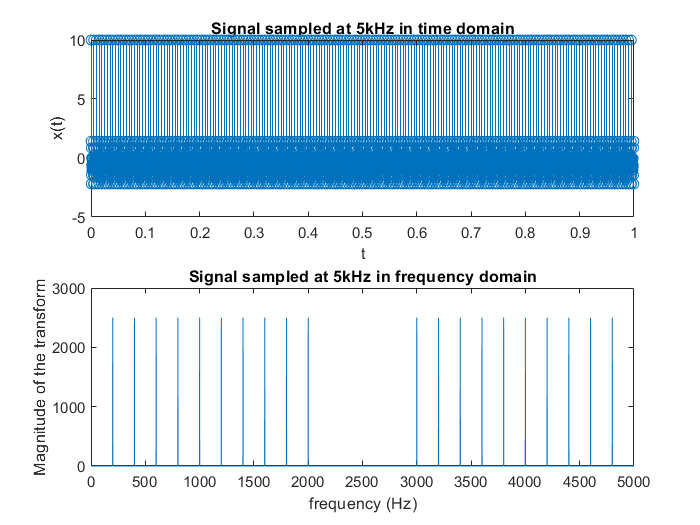

clear all;
close all;
clc;

f = 200; % Signal fundamental frequency of 200Hz.
fs= 5000; % Sampling frequency of 5kHz.
f_cheating = 50000; % "Cheating" frequency, simulate we are dealing with "analogue" signal whereas we are not.
N = 5000; % Since duration of the signal is 1s, and fs=5kHz, we need 5000 samples.
n = 0:N-1;
T= 1/fs; % Sample period.
x = zeros(10,5000); % Matrix for the whole signal
for i = 1:10
    x(i,:) = cos(2*pi*i*f*n*T);
end

% for j = 1:10
%     figure;
%     plot(n*T, x(j,:))
% end
signal_supersition = sum(x, 1);
subplot(2,1,1);
stem(n*T, signal_supersition);
xlabel('t');
ylabel('x(t)');
title('Signal sampled at 5kHz in time domain');
soundsc(signal_supersition);

fft_for_signal = fft(signal_supersition);
f = 0:4999;
subplot(2,1,2);
plot(f, abs(fft_for_signal));
xlabel('frequency (Hz)');
ylabel('Magnitude of the transform');
title('Signal sampled at 5kHz in frequency domain');

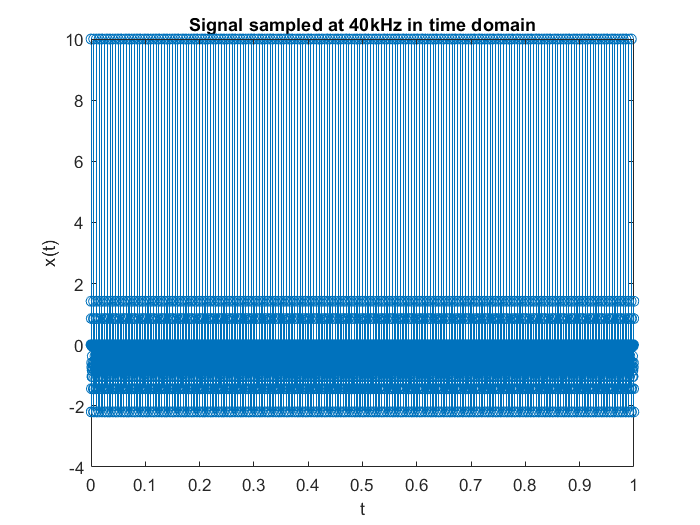

figure
% Since the required sampling frequency after doing up sampling is not a
% integral multiple of the original sampling frequency, we have to firt do
% the up sampling, then do the down sampling. Meaning, first do upsampling by
% 8 times, then down sample by 5 times.
signal_interleave_with_zeros = zeros(1, 40000);
index = 1;
for i = 1:40000
    if mod(i, 8) == 1
        signal_interleave_with_zeros(i) = signal_supersition(index);
        index = index + 1;
    end
end
k = 0:1/40000:39999/40000;
stem(k, signal_interleave_with_zeros)
xlabel('t');
ylabel('x(t)');
title('Signal sampled at 40kHz in time domain');

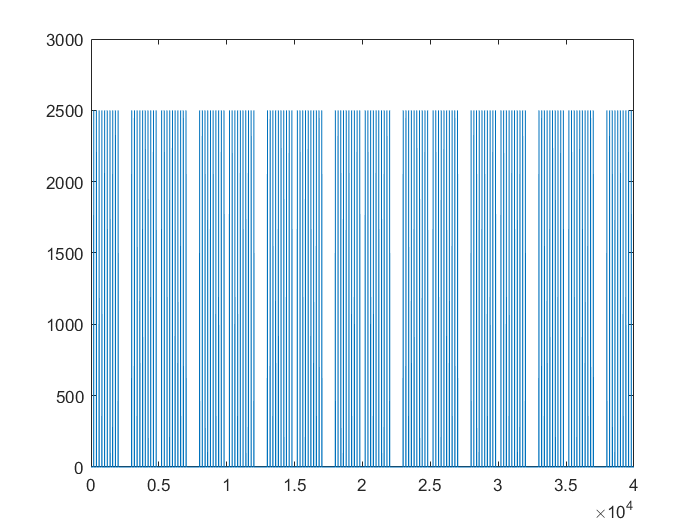

fft_for_upsampling = fft(signal_interleave_with_zeros);
f = 0:39999;
plot(f, abs(fft_for_upsampling));

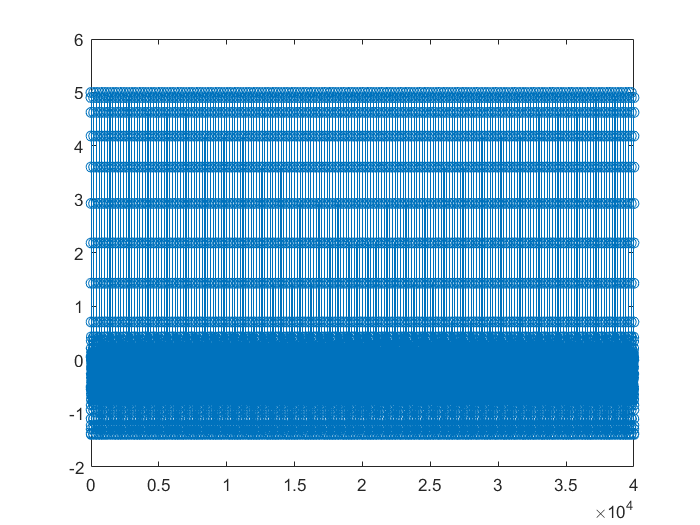


% As we can see in the frequency domain, the transform of the upsampling
% samples are the copies of the original samples, this means that the
% transform of the original samples was "compressed" within (0, 2*pi),
% where 2*pi denotes the sampling frequency, and since we upsample the
% original samples by a factor of 8, from 0 to 2*pi in the frequency
% domain, it contains 8 copies of the original transform.

% Firstly, filter out the redundant copies in the frequency domain.
% Here in order to make sure that after doing inverse transform, we
% still have the same signal amplitude as the signal before doing
% upsampling, we multiply the amplitude of the fourier transform for the
% upsampling signal by 8.
fft_for_upsampling_after_remove_copies=  [8*fft_for_upsampling(1:2501), zeros(1, 37499)];
% fft_for_upsampling_after_remove_copies=  [8*fft_for_upsampling(1:5001), zeros(1, 34999)];
% Since for this transfrom we have 0 padding, the inverse transform is of
% complex number, we take the real part of these complex numbers.
signal_after_upsampling = real(ifft(fft_for_upsampling_after_remove_copies));
n = 0:39999;
stem(n, signal_after_upsampling); 

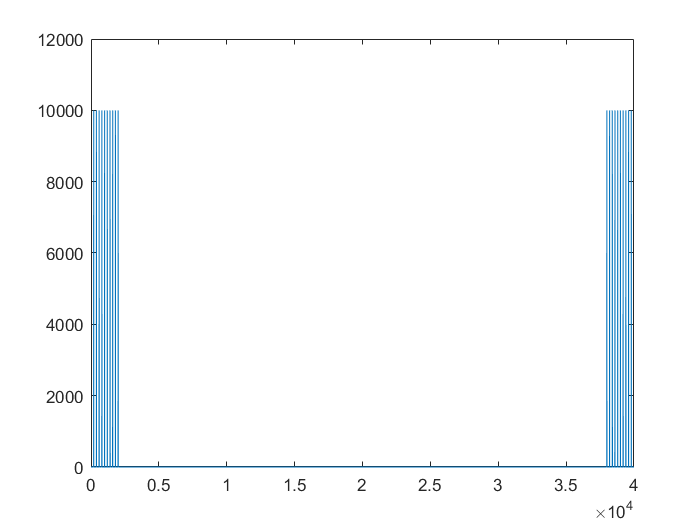


% Secondly, before downsampling the signal, recall the Nyquist sampling
% theorem, here in order to recover the signal, we also have to deal with
% the aliasing before transform back to time domain. So to some extend, we
% are sampling the sampled signal here.

test = fft(signal_after_upsampling);
k = 0:39999;
plot(k, abs(test))

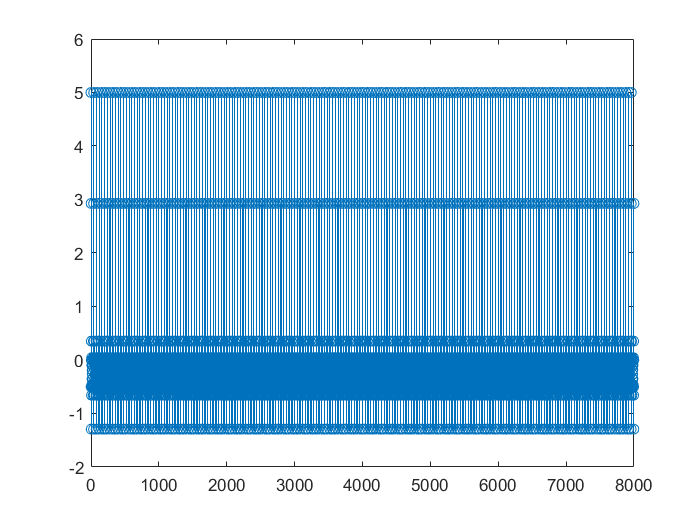


% First filter out the frequency component that is higher than pi/5, which
% is 8000Hz/5 = 1600Hz in the frequency domain.
fft_for_signal_after_antialiasing_filtering_before_downsampling = [fft_for_upsampling_after_remove_copies(1:2001), zeros(1, 37999)];
% fft_for_signal_after_antialiasing_filtering_before_downsampling = [fft_for_upsampling_after_remove_copies(1:5001), zeros(1, 34999)];
% k= 0:39999;
% plot(k, abs(fft_for_signal_after_antialiasing_filtering_before_downsampling));

signal_after_antialiasing_filter = real(ifft(fft_for_signal_after_antialiasing_filtering_before_downsampling));

signal_after_downsampling = zeros(1, 8000);
index = 1;
for i = 1:40000
    if mod(i, 5) == 1
        signal_after_downsampling(index) = signal_after_antialiasing_filter(i);
        index = index + 1;
    end
end
k = 0:7999;
stem(k, signal_after_downsampling);

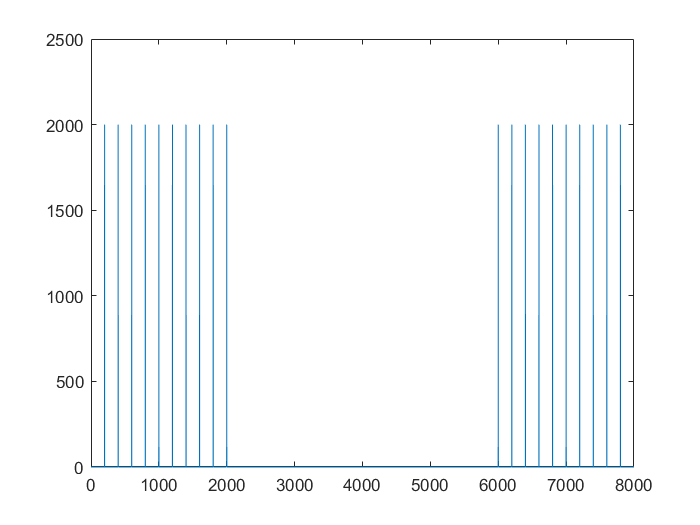

test = fft(signal_after_downsampling);
plot(k, abs(test));

soundsc(signal_after_downsampling);
% soundsc(signal_after_downsampling*10/3.5);
